SAMPLES_SECOND = 8000;

Generar RUIDO GAUSIANO

8000 por muestras

 por segundos

0 por 0dbW

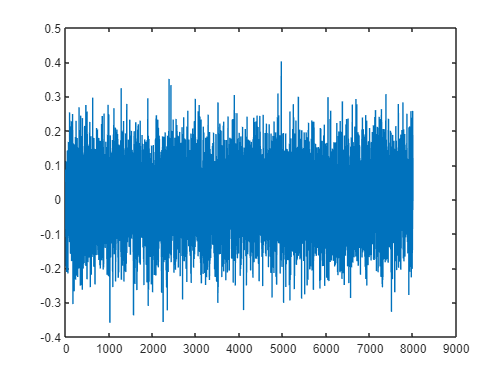

gausian_noise = wgn(SAMPLES_SECOND+1,1,.01,1,1,'linear');
figure(1);
plot(gausian_noise)

LECTURA DE AUDIO DE VOZ

8,000 Muestras por segundo

monoaural

PCM 8 Bits por muestras

[y, Fs] = audioread("Audios\grape-juice.wav");
%{
sound(y,Fs);
y;
plot(y);
%}

realizar down sampling

    -resamplee Fs -> 8k

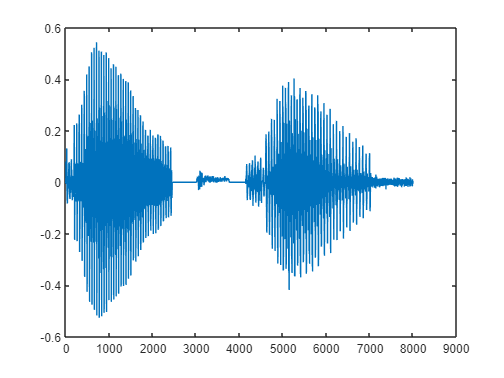

s_down_resample = resample(y, SAMPLES_SECOND, Fs);

m_t = s_down_resample(1:(SAMPLES_SECOND+1)); %cut one second final message signal
plot(m_t);

sound(m_t,SAMPLES_SECOND);

NORMALIZAR 

    0 - 255

    0 - 1

normalizo la señal y el ruido gausiano

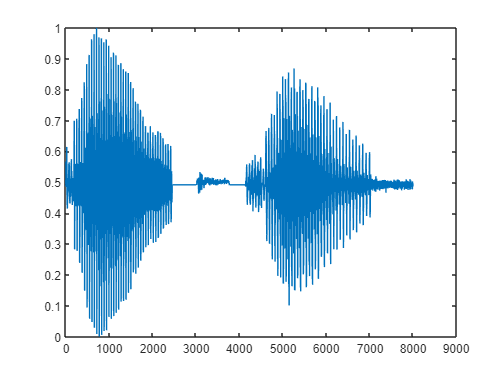

norm_value = normalize(m_t,'range');
%norm_value = rescale(norm_value, 0, 255);

plot(norm_value);

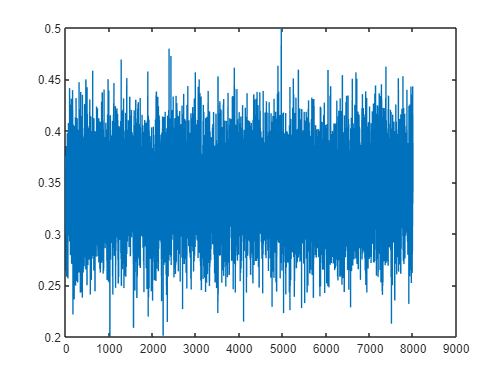

%gausian_noise = normalize(gausian_noise,'range');
gausian_noise = rescale(gausian_noise, .2, .5);
%hold on;
plot(gausian_noise);

noisesound = gausian_noise + norm_value;
%sound(noisesound,SAMPLES_SECOND);

potencia promedio de la señal


$$\textrm{SNR}=10*\log_{10} \;\left(\frac{P_{\textrm{SIG}} }{p_{\textrm{NOISE}} }\right)$$


Para que la Voz sea Inteligible, la SNR debe de estar entre 5db a 10db.

La calidad de la voz tendria que estar en un rango mayor de 7db para conservar buena Calidad.

pow_noise =  gausian_noise'*gausian_noise / length(gausian_noise);
pow_voice =  norm_value'*norm_value  / length(norm_value);
snr_signal = pow_voice / pow_noise;
db_signal_snr = 10*log10(snr_signal) 

db_signal_snr = 3.2782

%db_signal_snr = snr(norm_value, gausian_noise)


$$\frac{P_{\mathrm{SIG}\;} }{{10}^{\frac{\mathrm{SNR}}{10}} }=P_{\mathrm{NOISE}}$$


La potencia de ruido para obtener determinada SNR

Diferencias entre SIR y SNR

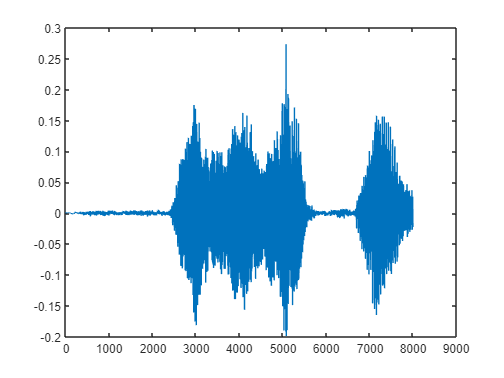

[y, Fs] = audioread("Audios\seriously.wav");
y= y(:,1); % Read one chann
s_down_resample = resample(y, SAMPLES_SECOND, Fs);
m_t = s_down_resample(1:(SAMPLES_SECOND+1)); %cut one second final message signal
plot(m_t);

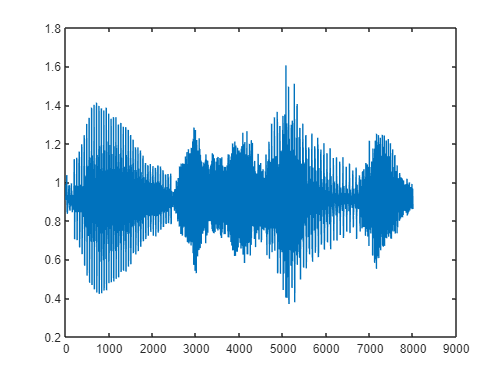

signal_interference = normalize(m_t,'range');
sum_signals = signal_interference + norm_value;
plot(sum_signals);

sound(sum_signals,SAMPLES_SECOND);

es una medida comparativa entre la potencia de señal y la potencia de las interferencias o del ruido, son utiles solo si el BER es una funcion monotonica, SIR puede llegar a tener valores menores de 1db, lo que hace que predominen las interferencias. 

pow_interference =  signal_interference'*signal_interference  / length(signal_interference);
rsi_signal = pow_interference /pow_voice;
db_signal_rsi = 10*log10(rsi_signal) 

db_signal_rsi = -1.3444